# Integració numérica

#### Matlab - Integracio adaptativa

F = @(x)(humps(x));
a = 0;
b = 1;
tol = 1.05e-6;
quadgui(F,a,b,tol);

Integracion adaptavi: es fa varies interpolacions polinómiques recursivament  fins que aquest s'atisfá la tolerancia

integral(@(x)humps(x), 0, 1, 'RelTol', 1e-8, 'AbsTol', 1e-13)

ans =        29.858

#### Metode Montecarlo

integral(@(x)x.^2, 0, 1)

ans =       0.33333

k = 0;
m = 100000;
for n=1:m
    x = rand;
    y = rand;
    if y < x^2
        k = k+1;
    end
end
valor_aprx = k/m       %% cuants dels tests que hem fet estan dins de l'area

valor_aprx =       0.33286

# Trapezi i Simpson

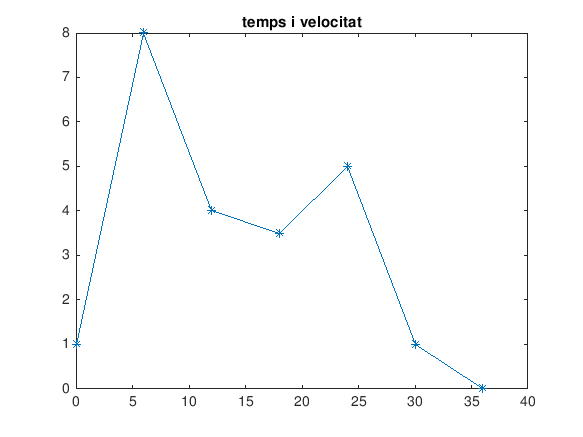

% Exercici Usain Bolt
time = 0:6:36;
vel = [1 8 4 3.5 5 1 0];
plot(time, vel, '-*'), title('temps i velocitat')

w = [1 2*ones(1, length(time)-2) 1];
h = time(2)-time(1);
T = sum(w.*vel.*h/2)    % Trapezi

T =    132

ws = [1 4 2 4 2 4 1];
S = sum(ws.*vel*h/3)    % Simpson

S =    138

trapz(time, vel)

ans =    132

cumtrapz(time, vel)

ans =             0           27           63         85.5          111          129          132
